# 2008 Value and Optimal Savings and Consumption Given Stimulus

This is the example vignette for function: [**snw_v08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/splanneralt/snw_v08_jaeemk.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This is simialr to [**snw_evuvw20_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/splanneralt/snw_evuvw20_jaeemk.m), but for the 2008 Bush stimulus. [**snw_v08p08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_v08p08_jaeemk.m) already solved for optimal policy and value functions in 2008, given expected unemployment shock in 2009. In this function, given some stimulus amount, we use [**snw_a4chk_wrk_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_a4chk_wrk_bisec_vec.m) to compute the updated optimal V and C in 2008 given the stimulus amount, based on the alues for V and C without stimulus computed by [**snw_v08p08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_v08p08_jaeemk.m).

Note that [**snw_a4chk_wrk_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_a4chk_wrk_bisec_vec.m) computes the adjustment in the savings state that would be equivalent to the increase in stimulus amount (which is not a state variable) to current resources, this is faster than resolving 2008 optimal V and C at specific stimulus check amount levels.

Note [**snw_evuvw20_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/splanneralt/snw_evuvw20_jaeemk.m) has EVUVW, but here, we only have V08, because in the 2020 problem, households receive checks ex-post of the COVID MIT shocks in 2020 and the EVUVW is the weighted average in V between the MIT unemployed and non-shock employed state. In 2008, however, there are no shocks yet, the state-space is the same as normal, the only difference is that households might receive stimulus checks from Bush. The Bush stimulus is provided ex-ante of the shock realization. The 2009 shocks due to the great recession is not a MIT shock, but expected shock. The effect of the 2009 shock on consumption, savings is solved by [**snw_v08p08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_v08p08_jaeemk.m). The expectation over shock, in another word, for the [**snw_v08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/splanneralt/snw_v08_jaeemk.m) is already included in EV' in 2008 for 2009.

## Solve 2008 Value and Policy Function with SNW_V08p08_JAEEMK

Solve for the Value and Policy functions in 2008 given expected unemployment shock that is specific to age and education group in 2009, no stimulus amounts.

First, set various parameters

% 1. Paramters
% Parameters
mp_more_inputs = containers.Map('KeyType','char', 'ValueType','any');
mp_more_inputs('fl_ss_non_college') = 0.225;
mp_more_inputs('fl_ss_college') = 0.271;
fl_p50_hh_income_07 = 54831;
mp_more_inputs('fl_scaleconvertor') = fl_p50_hh_income_07;

% st_param_group = 'default_small';
% st_param_group = 'default_dense';
st_param_group = 'default_docdense';
mp_params = snw_mp_param(st_param_group, false, 'tauchen', false, 8, 8, mp_more_inputs);
mp_params('beta') = 0.95;
    
% Control parameters
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_a4chk') = false;
mp_controls('bl_print_a4chk_verbose') = false;
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_print_v08p08_jaeemk') = false;
mp_controls('bl_print_v08p08_jaeemk_verbose') = false;
mp_controls('bl_print_v08_jaeemk') = true;
mp_controls('bl_print_v08_jaeemk_verbose') = true;

Second, solve the steady-state problem, same as employed results in 2009.

% 2. Solve value steady state (2009 employed)
[V_VFI_ss, ap_VFI_ss, cons_VFI_ss, mp_valpol_more_ss] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=530.633


inc_VFI = mp_valpol_more_ss('inc_VFI');
spouse_inc_VFI = mp_valpol_more_ss('spouse_inc_VFI');
total_inc_VFI = inc_VFI + spouse_inc_VFI;
V_emp_2009 = V_VFI_ss;
% Solve for probability mass, needed for pre-compute
[Phi_true] = snw_ds_main_vec(mp_params, mp_controls, ap_VFI_ss, cons_VFI_ss, mp_valpol_more_ss);

Completed SNW_DS_MAIN_VEC;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=1271.649


% Solve for household head and spouse income and sum to total income. 
inc_VFI = mp_valpol_more_ss('inc_VFI');
spouse_inc_VFI = mp_valpol_more_ss('spouse_inc_VFI');
total_inc_VFI = inc_VFI + spouse_inc_VFI;

Third, solve the unemployment problem in 2009. With 2009 specific unemployment parameters calibrated and found from data. Using $b$ calibrated by [**snw_calibrate_2009_b**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/calibrate/snw_calibrate_2009_b.m)**.**

% 3. Solve value unemployed 2009
% Set Unemployment Related Variables
mp_params('xi') = 0.532;
% Calibrated by snw_calibrate_2009_b
mp_params('b') = 0.37992;
mp_params('a2_covidyr') = mp_params('a2_greatrecession_2009');
mp_params('TR') = 100/fl_p50_hh_income_07; % Value of a stimulus check (can receive multiple checks). TO DO: Update with alternative values;
[V_unemp_2009] = snw_vfi_main_bisec_vec(mp_params, mp_controls, V_VFI_ss);

Completed SNW_VFI_MAIN_BISEC_VEC 1 Period Unemp Shock;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=326.1213


Fourth, solve the 2008 problem, with 2008-specific value and policy functions.

% 4. Value and Optimal choice in 2009
[V_2008, ap_2008, cons_2008, ev_empshk_2009] = ...
    snw_v08p08_jaeemk(mp_params, mp_controls, V_emp_2009, V_unemp_2009);

Completed SNW_VFI_MAIN_BISEC_VEC 1 Period Unemp Shock;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=516.0952
Completed SNW_V08P08_JAEEMK;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time=522.6257


% 5. pre-compute
cl_st_precompute_list = {'a', ...
    'inc', 'inc_unemp', 'spouse_inc', 'spouse_inc_unemp', 'ref_earn_wageind_grid'};
mp_controls('bl_print_precompute_verbose') = false;
[mp_precompute_res] = snw_hh_precompute(mp_params, mp_controls, cl_st_precompute_list, ap_VFI_ss, Phi_true);

Wage quintile cutoffs=0.4645     0.71528      1.0335      1.5632
SNW_HH_PRECOMPUTE: Finished Age Group:1 of 82, time-this-age:3.2746
SNW_HH_PRECOMPUTE: Finished Age Group:2 of 82, time-this-age:3.2852
SNW_HH_PRECOMPUTE: Finished Age Group:3 of 82, time-this-age:3.3869
SNW_HH_PRECOMPUTE: Finished Age Group:4 of 82, time-this-age:3.4589
SNW_HH_PRECOMPUTE: Finished Age Group:5 of 82, time-this-age:3.254
SNW_HH_PRECOMPUTE: Finished Age Group:6 of 82, time-this-age:3.3465
SNW_HH_PRECOMPUTE: Finished Age Group:7 of 82, time-this-age:3.4109
SNW_HH_PRECOMPUTE: Finished Age Group:8 of 82, time-this-age:3.4221
SNW_HH_PRECOMPUTE: Finished Age Group:9 of 82, time-this-age:3.4152
SNW_HH_PRECOMPUTE: Finished Age Group:10 of 82, time-this-age:3.4065
SNW_HH_PRECOMPUTE: Finished Age Group:11 of 82, time-this-age:3.1869
SNW_HH_PRECOMPUTE: Finished Age Group:12 of 82, time-this-age:3.3572
SNW_HH_PRECOMPUTE: Finished Age Group:13 of 82, time-this-age:3.4748
SNW_HH_PRECOMPUTE: Finished Age Group:14 of 82, 

## Solve for 2008 Value and Consumption with 0 and 2 Checks

Now we use the [**snw_v08_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/splanneralt/snw_v08_jaeemk.m) function, which takes as inputs the 2008-specific value and policy we have already found, to compute the 2008 value and consumption based on different stimulus amounts via asset-equivalent transformation given stimulus amounts.

FIrst, obtain V and C with zero stimulus.

% Call Function
welf_checks = 0;
[V_2008_check0, C_2008_check0] = snw_v08_jaeemk(...
    welf_checks, mp_params, mp_controls, V_2008, cons_2008, mp_precompute_res);

Solve for V_2008_check for 0 stimulus checks
Completed SNW_A4CHK_WRK_BISEC_VEC;SNW_MP_PARAM=st_biden_or_trump_undefined;welf_checks=0;TR=0.0018238;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time cost=70.6533
Completed SNW_V08_JAEEMK;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;timeEUEC=3e-05
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim     numel      rowN      colN           sum         mean       std      coefvari      min          max    
                    _    ___    ____    ________    ____    _____

% Call Function

Second, obtain V and C with two stimulus checks.

welf_checks = 2;
[V_2008_check2, C_2008_check2] = snw_v08_jaeemk(...
    welf_checks, mp_params, mp_controls, V_2008, cons_2008, mp_precompute_res);

Solve for V_2008_check for 2 stimulus checks
Completed SNW_A4CHK_WRK_BISEC_VEC;SNW_MP_PARAM=st_biden_or_trump_undefined;welf_checks=2;TR=0.0018238;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;time cost=71.7044
Completed SNW_V08_JAEEMK;SNW_MP_PARAM=default_docdense;SNW_MP_CONTROL=default_test;timeEUEC=2.16e-05
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim     numel      rowN      colN           sum         mean       std      coefvari      min          max    
                    _    ___    ____    ________    ____    __

Differences between Checks in Expected Value and Expected Consumption

mn_V_U_gain_check = V_2008_check2 - V_2008_check0;
mn_MPC_U_gain_share_check = (C_2008_check2 - C_2008_check0)./(welf_checks*mp_params('TR'));

## Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and C with Check

The difference between V and V with Check, marginal utility gain given the check.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

MEAN(MN_V_GAIN_CHECK(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27

Graph Mean Values:

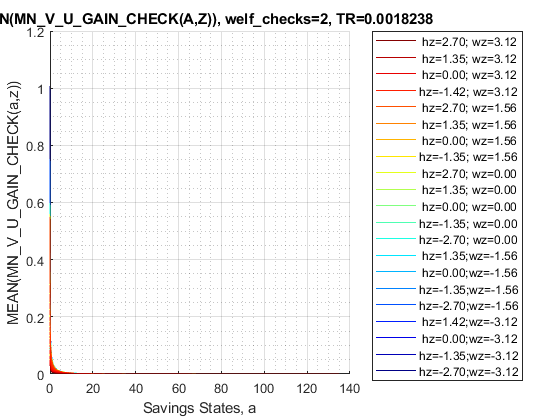

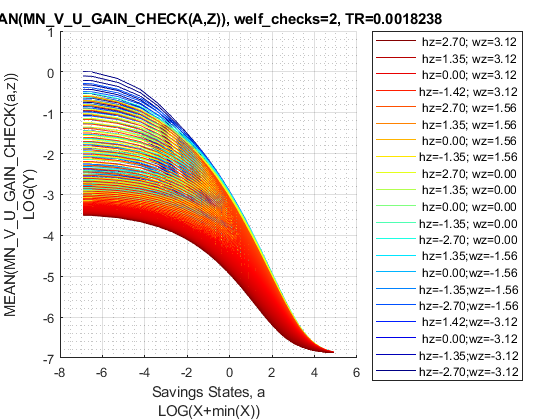

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

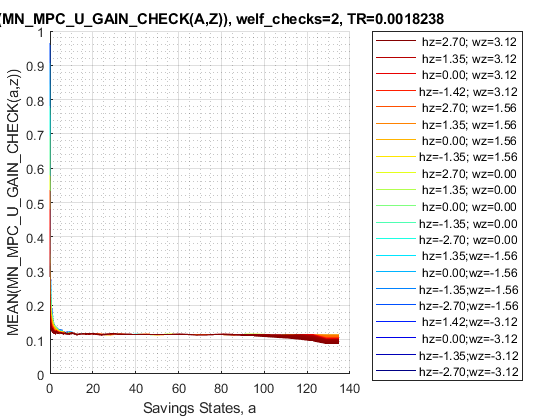

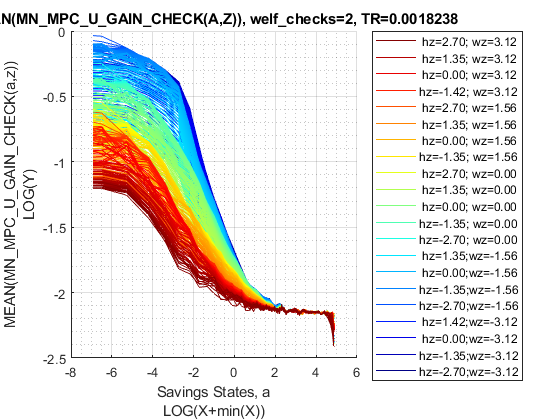

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Marginal Value and MPC over Y(a,eta), Conditional On Kids, Marry, Age, Education

Income is generated by savings and shocks, what are the income levels generated by all the shock and savings points conditional on kids, marital status, age and educational levels. Plot on the Y axis MPC, and plot on the X axis income levels, use colors to first distinguish between different a levels, then use colors to distinguish between different eta levles. 

Set Up date, Select Age, unmarried, no kids, lower education:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
% 38 year old, unmarried, no kids, lower educated
% Only Household Head Shock Matters so select up to 'n_eta_H_grid'
mn_total_inc_jemk = total_inc_VFI(19,:,1:mp_params('n_eta_H_grid'),1,1,1);
mn_V_W_gain_check_use = V_2008_check2 - V_2008_check0;
mn_C_W_gain_check_use = C_2008_check2 - C_2008_check0;

Select Age, Education, Marital, Kids Count:s

% Selections
it_age = 21; % +18
it_marital = 1; % 1 = unmarried
it_kids = 1; % 1 = kids is zero
it_educ = 1; % 1 = lower education
% Select: NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
mn_C_W_gain_check_jemk = mn_C_W_gain_check_use(it_age, :, 1:mp_params('n_eta_H_grid'), it_educ, it_marital, it_kids);
mn_V_W_gain_check_jemk = mn_V_W_gain_check_use(it_age, :, 1:mp_params('n_eta_H_grid'), it_educ, it_marital, it_kids);
% Reshape, so shock is the first dim, a is the second
mt_total_inc_jemk = permute(mn_total_inc_jemk,[3,2,1]);
mt_C_W_gain_check_jemk = permute(mn_C_W_gain_check_jemk,[3,2,1]);
mt_C_W_gain_check_jemk(mt_C_W_gain_check_jemk<=1e-10) = 1e-10;
mt_V_W_gain_check_jemk = permute(mn_V_W_gain_check_jemk,[3,2,1]);
mt_V_W_gain_check_jemk(mt_V_W_gain_check_jemk<=1e-10) = 1e-10;
% Generate meshed a and shock grid
[mt_eta_H, mt_a] = ndgrid(eta_H_grid(1:mp_params('n_eta_H_grid')), agrid);

## Marginal Value Gains, Color as Shock, Conditional on Age, Marital, Kids, and Education

How do shocks and a impact marginal value. First plot one asset level, variation comes only from increasingly higher shocks:

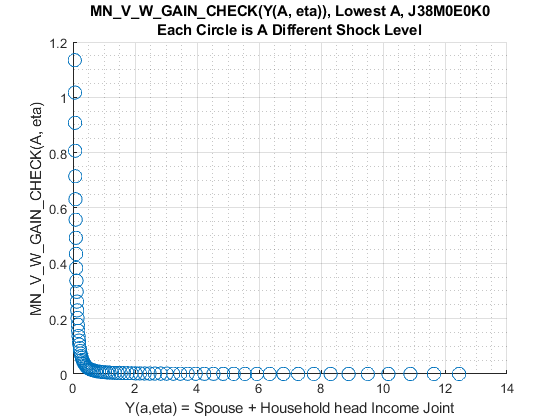

figure();
it_a = 1;
scatter((mt_total_inc_jemk(:,it_a)), (mt_V_W_gain_check_jemk(:,it_a)), 100);
title({'MN\_V\_W\_GAIN\_CHECK(Y(A, eta)), Lowest A, J38M0E0K0', ...
    'Each Circle is A Different Shock Level'});
xlabel('Y(a,eta) = Spouse + Household head Income Joint');
ylabel('MN\_V\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

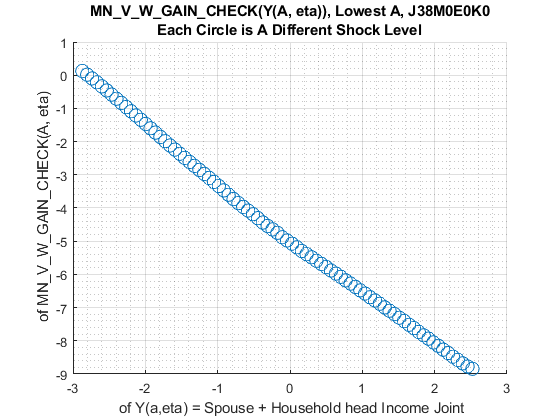

figure();
it_shock = 1;
scatter(log(mt_total_inc_jemk(:,it_a)), log(mt_V_W_gain_check_jemk(:,it_a)), 100);
title({'MN\_V\_W\_GAIN\_CHECK(Y(A, eta)), Lowest A, J38M0E0K0', ...
    'Each Circle is A Different Shock Level'});
xlabel(' of Y(a,eta) = Spouse + Household head Income Joint');
ylabel(' of MN\_V\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

Plot all asset levels:

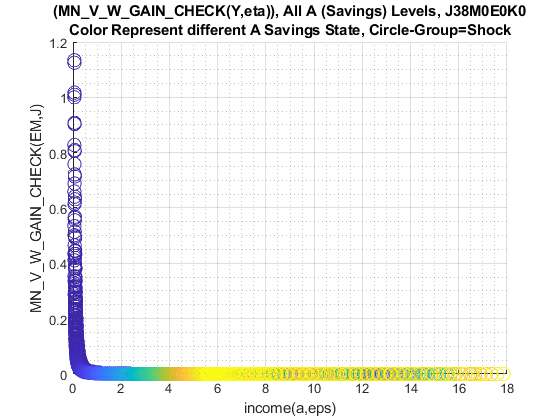

figure();
scatter((mt_total_inc_jemk(:)), (mt_V_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_V\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('MN\_V\_W\_GAIN\_CHECK(EM,J)');
grid on;
grid minor;

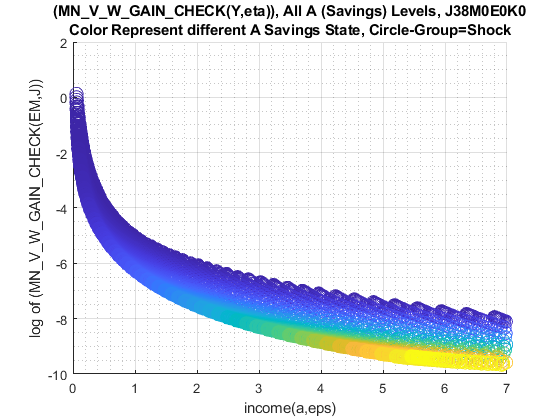

figure();
scatter((mt_total_inc_jemk(:)), log(mt_V_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_V\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('log of (MN\_V\_W\_GAIN\_CHECK(EM,J))');
xlim([0,7]);
grid on;
grid minor;

## Marginal Consumption Gains, Color as Shock, Conditional on Age, Marital, Kids, and Education

How do shocks and a impact marginal value. First plot one asset level, variation comes only from increasingly higher shocks:

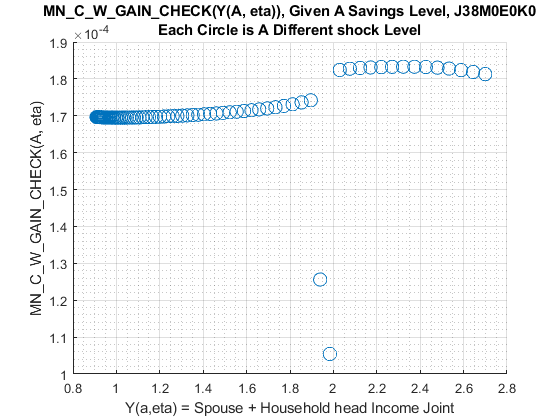

figure();
it_a = 50;
scatter(log(mt_total_inc_jemk(:,it_a)), mt_C_W_gain_check_jemk(:,it_a), 100);
title({'MN\_C\_W\_GAIN\_CHECK(Y(A, eta)), Given A Savings Level, J38M0E0K0', ...
    'Each Circle is A Different shock Level'});
xlabel('Y(a,eta) = Spouse + Household head Income Joint');
ylabel('MN\_C\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

Plot all asset levels:

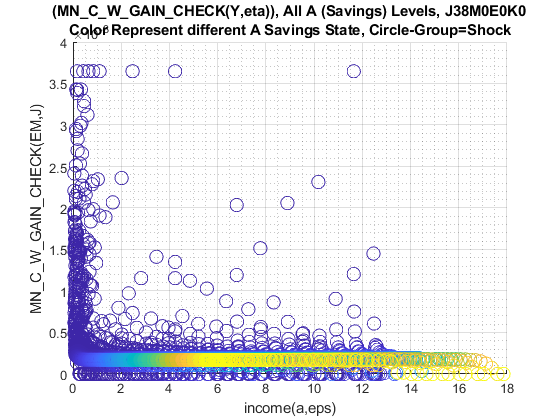

figure();
scatter((mt_total_inc_jemk(:)), (mt_C_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_C\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('MN\_C\_W\_GAIN\_CHECK(EM,J)');
grid on;
grid minor;

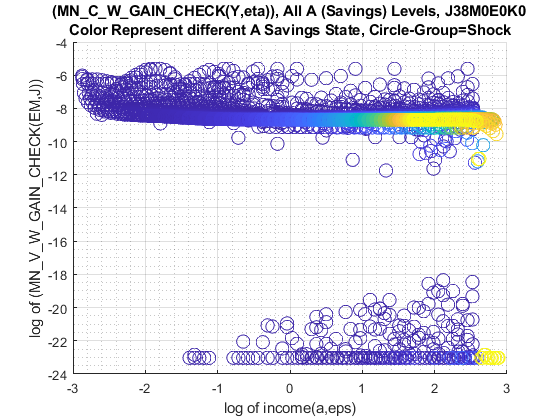

figure();
scatter(log(mt_total_inc_jemk(:)), log(mt_C_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_C\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('log of income(a,eps)');
ylabel('log of (MN\_V\_W\_GAIN\_CHECK(EM,J))');
grid on;
grid minor;

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption Function
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

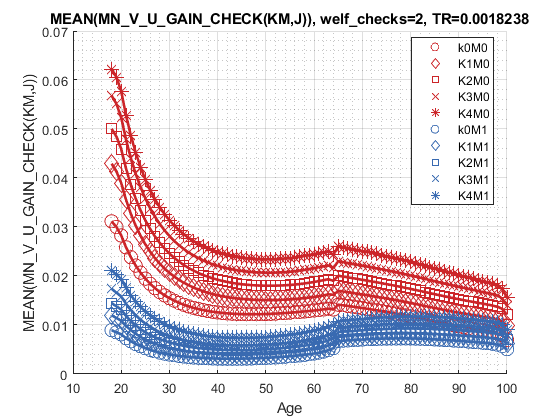

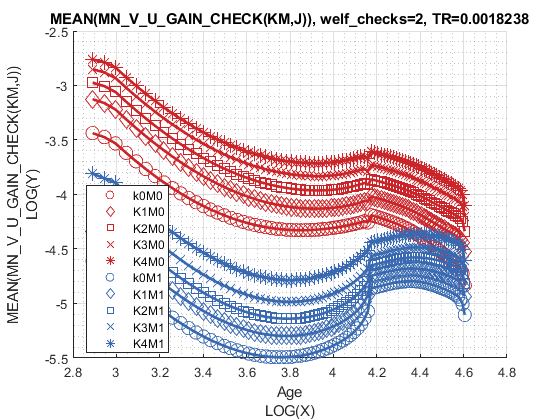

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

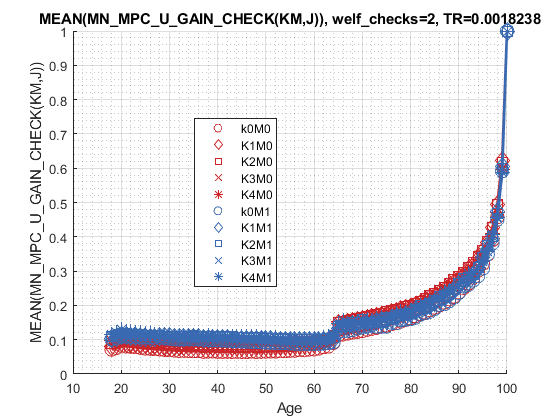

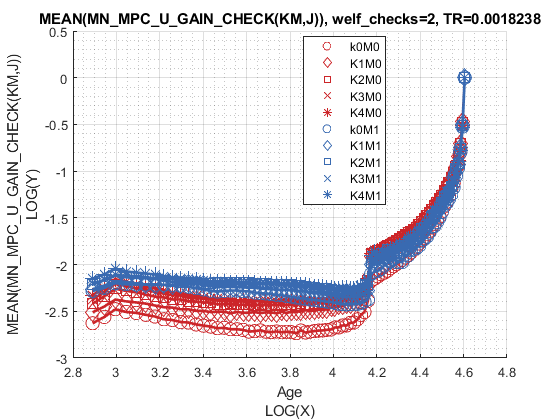

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0018238  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

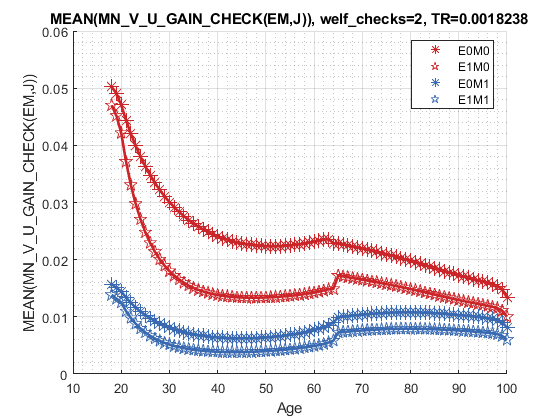

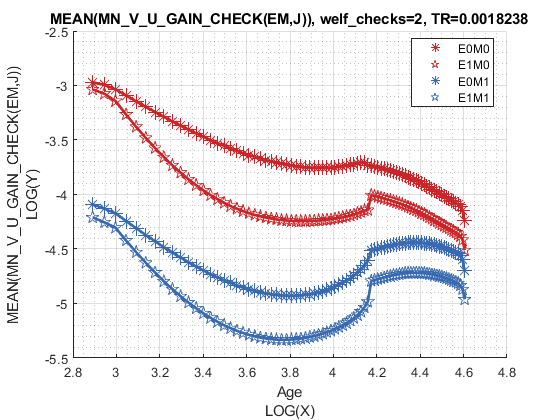

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

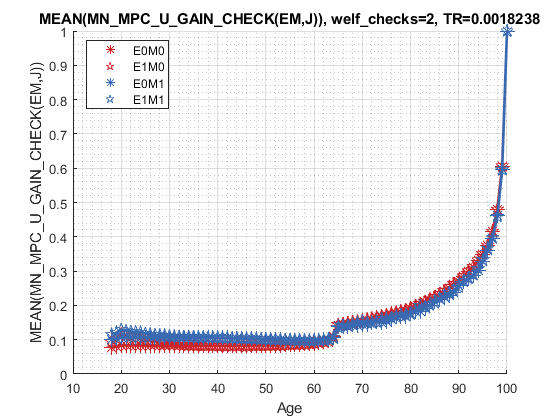

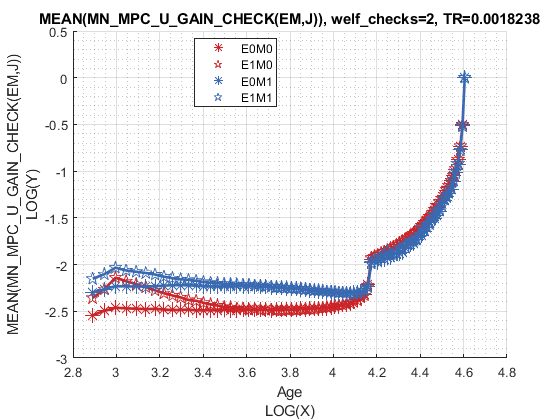

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);